## Assignment 1

### Task 1

Use a for loop to estimate the value of pi. The precision depends on the iteration times set by users. 

First we should define the function that conduct the experiment and return the final probability. 

%Conduct the experiment for certain iteration times.
%nop = number of points
function prob = for_loop(nop)
    in_cnt = 0;
    prob = 0;
    for cnt = 1:nop
        %poi represent the random point generated in the square
        poi = rand(2,1);
        %Those fall in to the circle contribute to the count
        if poi(1)^2+poi(2)^2 < 1.0
            in_cnt = in_cnt + 1;
            prob = in_cnt / cnt;
        else
            continue
        end
    end
end

    Next we conduct the experiment for 1e6 times.

pi_for = for_loop(100000);
disp(pi_for*4)

    3.1408



We can use different nop and plot the corresponding relative error.

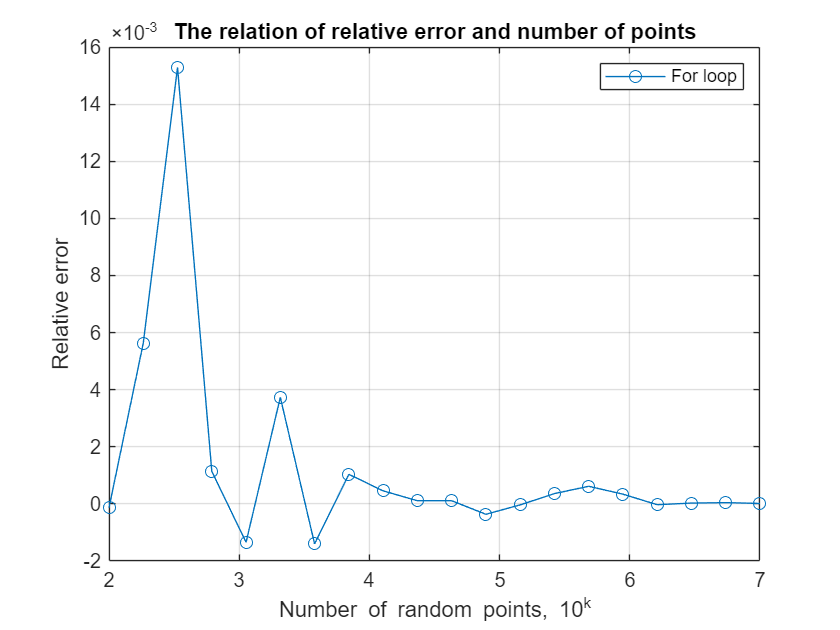

benchmark= linspace(2,7,20); % Benchmark nops are linear power of 10
error_list = zeros(size(benchmark));
for i = 1:length(benchmark)
    cnt = fix(10^benchmark(i));
    sample = zeros(1,10); % Take mean of 10 separate experiments
    for j = 1:length(sample)
        rel_error = (4*for_loop(cnt) - pi) / pi;
        sample(j) = rel_error;
    end
    rel = mean(sample);
    error_list(i) = rel;
end
figure;
plot(benchmark, error_list, '-o');
xlabel('Number of random points, 10^k');
ylabel('Relative error');
legend('For loop');
title('The relation of relative error and number of points');
grid on;

%saveas(gcf, '/MATLAB Drive/figs/relative_error.png')

We can also measure the runtime of each benchmark using tictoc.

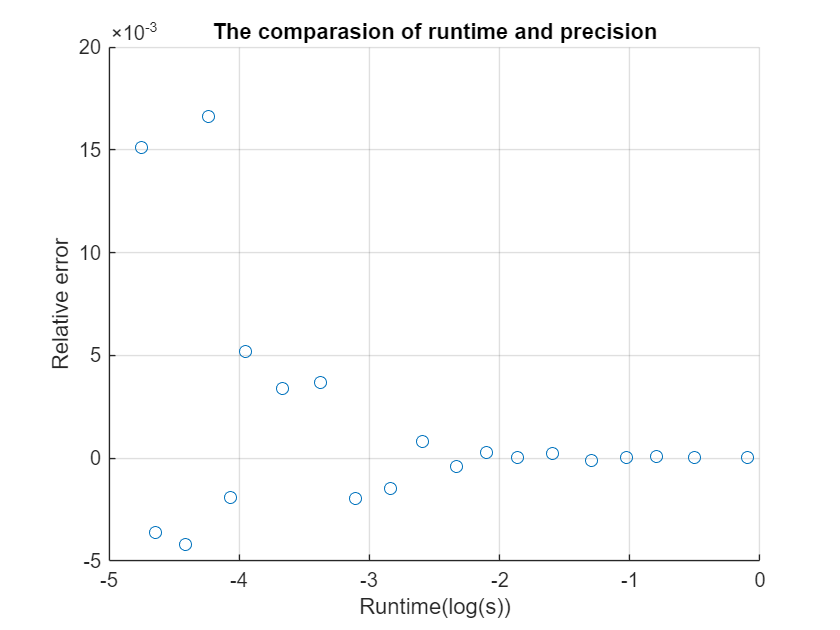

T_list = zeros(size(benchmark));
error_list2 = zeros(size(benchmark));
for i = 1:length(benchmark)
    tic;
    cnt = fix(10^benchmark(i));
    sample = zeros(1,10); % Take mean of 10 separate experiments
    for j = 1:length(sample)
        rel_error = (4*for_loop(cnt) - pi) / pi;
        sample(j) = rel_error;
    end
    rel = mean(sample);
    error_list2(i) = rel;
    T_list(i) = toc / 10;
end
lgT_list = log10(T_list); % Use logarithmic of time for explicity
figure;
scatter(lgT_list, error_list2); % Since the runtime measurment fluctuates while nop is small, we choose scatter to show the relation
xlabel('Runtime(log(s))');
ylabel('Relative error');
title('The comparasion of runtime and precision');
grid on;

%saveas(gcf, '/MATLAB Drive/figs/runtime.png')

### Task 2

This time we use the while loop to estimate pi without using the true value of pi. We know our experiment result will finally converge to the true value of pi if iterated infinite times, so the estimated true value is the output of experiment function with large noi. But suppose we don't know how large should the noi be, we should then consider the converge speed of the experiment: if the result does not update significantly in several bins, then we conclude that the result has reached certain precision.

Specficaly, we want the precision of 3 significant figures, we set the $\epsilon$ equals 1e-2. We take the bin to be the former 1e5 results, and measure bin range to compare to $\epsilon$. If the bin range is smaller than $\epsilon$ for continuously 100 times, while ends.

% Test whether the current update is below the bound of precision
% If below the bound, output true, else output false
function p = bin_test(data, end_i, bin_len, epslion)
      if bin_len >= end_i
          p = false;
      else
          % Take the former bin_len updates as a bin, then calculate the
          % range
          range = max(data((end_i-bin_len):end_i)) - min(data((end_i-bin_len):end_i));
          if range < epslion
              p = true;
          else
              p = false;
          end
      end
  end
             
% steps: the upper bound of numbers of continuous no_update steps.
% epsilon: the expected precision of the program
% Output the final estimation of pi and the steps needed to reach the
% precision
function [ratio, total_cnt] = exp_while(steps, epslion) 
    ratio = 0;
    in_cnt = 0;
    total_cnt = 0;
    no_update = 0;
    ratio_list = zeros(1,1e8); % pre-allocation for the results and set the upper bound of nop
    while no_update <= steps % Exit loop when continuous no update steps reach the uppe bound 
        poi = rand(2,1);
        total_cnt = total_cnt + 1;
        if total_cnt > 1e8
            error('List size too small');
        end
        if poi(1)^2+poi(2)^2 < 1.0
            in_cnt = in_cnt + 1;
        end
        ratio = in_cnt / total_cnt;
        ratio_list(total_cnt) = ratio;
        if bin_test(ratio_list, total_cnt, 100000, epslion)
            no_update = no_update + 1;
        else
            no_update = 0;
        end
    end
end

Next we conduct the experiment

[pi_while, tol] = exp_while(100, 1e-2); % User defined precision equals 1e-2
disp(pi_while*4);

    3.1382



disp(tol);

      101941



### Task 3

In task 2 we already convert it into a function. Now we add the graphical display to it.

function [ratio, total_cnt, points] = grap_while(steps, epslion) 
    ratio = 0;
    in_cnt = 0;
    total_cnt = 0;
    no_update = 0;
    ratio_list = zeros(1,1e8); % pre-allocation for the results
    points = []; 
    while no_update <= steps % Exit loop when continuous no update steps reach the uppe bound 
        poi = rand(1,2);
        total_cnt = total_cnt + 1;
        if total_cnt > 1e8
            error('List size too small');
        end
        if poi(1)^2+poi(2)^2 < 1.0
            in_cnt = in_cnt + 1;
            poi(end+1) = 0; % Color tag for inner points
        else
            poi(end+1) = 1; % Color tag for outer points
        end
        points = [points;poi]; % Storage the points in a matrix of 3 columns
        ratio = in_cnt / total_cnt;
        ratio_list(total_cnt) = ratio;
        if bin_test(ratio_list, total_cnt, 100000, epslion)
            no_update = no_update + 1;
        else
            no_update = 0;
        end
    end
end

Next we conduct the experiment and use the result to plot.

[pi_while, tol, points] = grap_while(100, 1e-2); % User defined precision equals 1e-2
disp(tol);

      104673



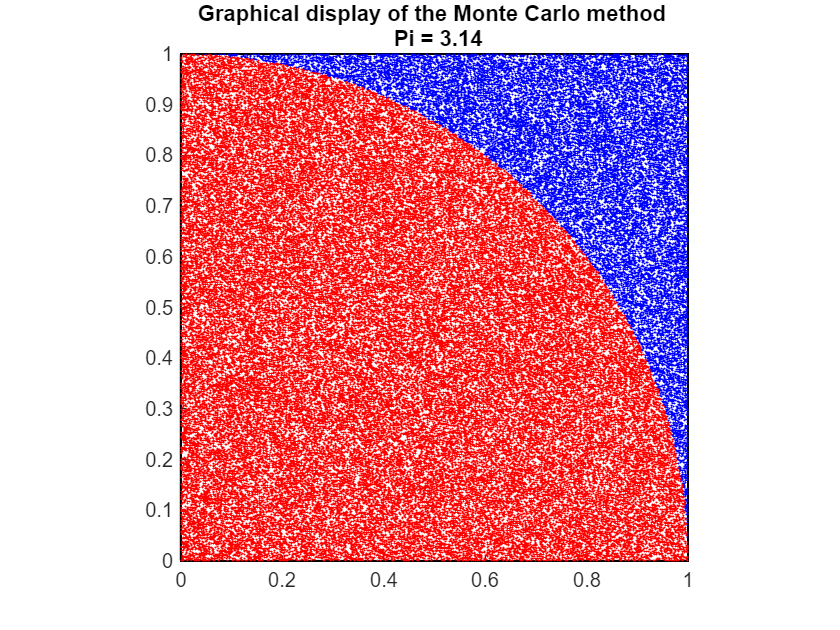

figure;
hold on;
axis equal;

rectangle('Position',[0 0 1 1],'EdgeColor','black','LineWidth', 1); % Draw the square
colors = zeros(size(points,1), 3); 
% If the third entry is 0, the point fall in the circle, red color (R=1, G=0, B=0)
% Or it's blue (R=0, G=0, B=1)
colors(points(:,3) == 0, :) = repmat([1, 0, 0], sum(points(:,3) == 0), 1); 
colors(points(:,3) == 1, :) = repmat([0, 0, 1], sum(points(:,3) == 1), 1); 

scatter(points(:,1), points(:,2), 1, colors,'filled')
xlim([0 1]);
ylim([0 1]);

title(sprintf('Graphical display of the Monte Carlo method \n Pi = %.2f',pi_while*4));
hold off;

%saveas(gcf, '/MATLAB Drive/figs/graphical_display.png')
export('Pi_est.mlx', format='pdf');